dataDirName = 'data';
if ~exist(dataDirName, 'dir')
  unzip('Data.zip', dataDirName);
end

dataDir = dir(dataDirName);

## Data Exploration

sim = 'sim1';
simIndex = 1;
simData = load(fullfile(dataDirName, 'simulations', sim, [sim '.mat']));

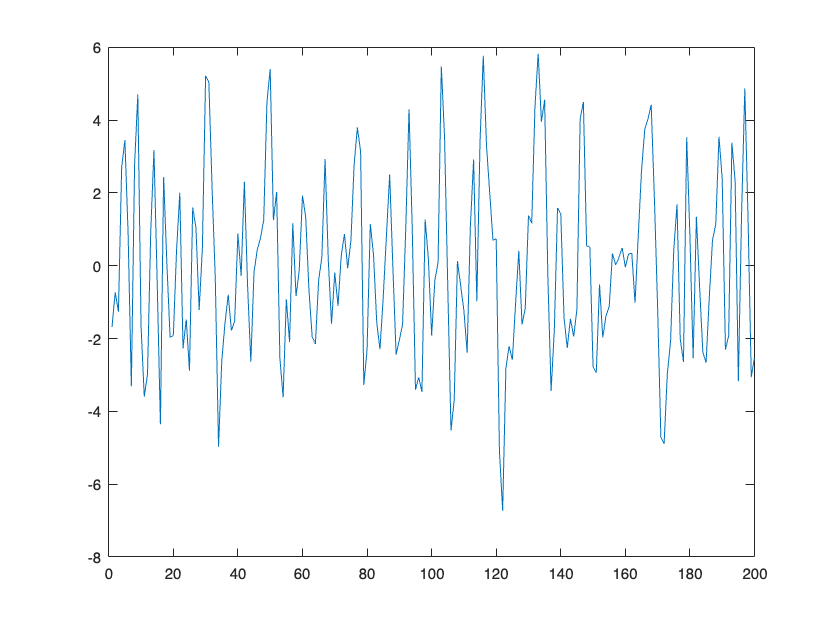

subject_idx = 1;

start_idx = simData.Ntimepoints * (subject_idx-1) + 1;
end_idx = simData.Ntimepoints * subject_idx;
ts = simData.ts(start_idx:end_idx,:);
channel1 = ts(:,1);
plot(channel1);

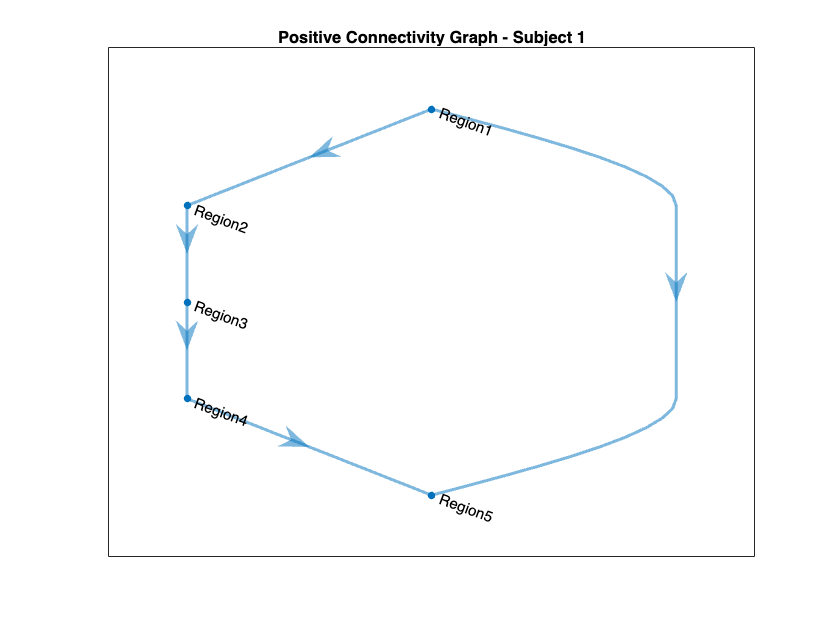

C = squeeze(simData.net(subject_idx, :, :));
nodenames=["Region1", "Region2", "Region3", "Region4", "Region5"];

G = digraph(C, nodenames, 'omitselfloops');

% Plot with edge weights
figure;
plot(G, 'Layout', 'layered', 'ArrowSize', 15, 'LineWidth', 2);
title(['Positive Connectivity Graph - Subject ', num2str(subject_idx)]);

ts = simData.ts;
net = simData.net;

addpath('notebooks/matlab/');

net(1,:,:)

ans = ans(:,:,1) =

    -1     0     0     0     0


ans(:,:,2) =

    0.3567   -1.0000         0         0         0


ans(:,:,3) =

         0    0.2334   -1.0000         0         0


ans(:,:,4) =

         0         0    0.4125   -1.0000         0


ans(:,:,5) =

    0.2854         0         0    0.4288   -1.0000


function [eeg_data, roi_activity] = simulate_eeg_from_network(fmri_neural_signals, connectivity_matrix)
% SIMULATE_EEG_FROM_NETWORK Generate simulated EEG data from fMRI neural signals
%
% Inputs:
%   fmri_neural_signals - Neural signals from fMRI (5 ROIs x 200 timepoints)
%   connectivity_matrix - Ground truth directed network connectivity matrix
%
% Outputs:
%   eeg_data - Simulated EEG data (channels x 6000 timepoints)
%   roi_activity - Latent ROI activity (3 ROIs x 6000 timepoints)

% Constants for EEG generation
n_rois_fmri = 5;           % Number of fMRI ROIs
n_rois_eeg = 3;            % Number of EEG ROIs (subset of fMRI ROIs)
n_times_fmri = 200;        % fMRI timepoints
n_times_eeg = 6000;        % EEG timepoints
n_channels = 64;           % Number of EEG channels

% Validate input dimensions
[rows_fmri, cols_fmri] = size(fmri_neural_signals);
if rows_fmri ~= n_rois_fmri || cols_fmri ~= n_times_fmri
    error('Expected fMRI neural signals to be %d ROIs x %d timepoints', n_rois_fmri, n_times_fmri);
end

% Select which fMRI ROIs to map to EEG ROIs (for example, first 3)
roi_mapping = 1:n_rois_eeg;  % Map first 3 fMRI ROIs to EEG ROIs

% Create time vectors for both modalities (normalized to [0,1])
t_fmri = linspace(0, 1, n_times_fmri);
t_eeg = linspace(0, 1, n_times_eeg);

% Interpolate fMRI neural signals to EEG time scale for selected ROIs
roi_activity = zeros(n_rois_eeg, n_times_eeg);
for roi = 1:n_rois_eeg
    fmri_roi = roi_mapping(roi);
    roi_activity(roi,:) = interp1(t_fmri, fmri_neural_signals(fmri_roi,:), t_eeg, 'pchip');
end

% Add event-related activity - extract events from fMRI data
% Find peaks in fMRI signal to identify events
events = [];
for roi = 1:n_rois_fmri
    [~, peaks] = findpeaks(fmri_neural_signals(roi,:), 'MinPeakHeight', mean(fmri_neural_signals(roi,:)) + std(fmri_neural_signals(roi,:)));
    events = unique([events, peaks]);
end

% Map fMRI event times to EEG timepoints
eeg_events = round(interp1(t_fmri, 1:n_times_fmri, t_eeg(events), 'nearest'));

% Generate EEG-specific events (higher temporal resolution)
n_extra_events = 50;  % Add more events only visible in EEG
extra_events = sort(randi([1, n_times_eeg], 1, n_extra_events));
all_eeg_events = sort(unique([eeg_events, extra_events]));

% Apply event-related modulation to ROI activity
event_duration = round(n_times_eeg / 100);  % Short event duration
for e = 1:length(all_eeg_events)
    event_start = all_eeg_events(e);
    event_end = min(event_start + event_duration, n_times_eeg);
    
    % Create small event-related perturbation
    for roi = 1:n_rois_eeg
        % Different amplitude for each ROI
        amplitude = 0.5 + 0.2*roi;
        
        % Apply event-related response with some jitter between ROIs
        for t = event_start:event_end
            time_offset = t - event_start;
            roi_activity(roi, t) = roi_activity(roi, t) + amplitude * exp(-(time_offset-3)^2/8);
        end
    end
end

% Generate lead field matrix: each ROI projects to a subset of channels
G = zeros(n_channels, n_rois_eeg);
ch_per_roi = ceil(n_channels / n_rois_eeg);

for roi = 1:n_rois_eeg
    % Select channels for this ROI with some spatial pattern
    start_ch = 1 + (roi-1) * ch_per_roi;
    end_ch = min(n_channels, roi * ch_per_roi);
    ch_range = start_ch:end_ch;
    
    % Create a realistic spatial pattern (strongest in the center, weaker at edges)
    for ch_idx = 1:length(ch_range)
        ch = ch_range(ch_idx);
        center = start_ch + floor(length(ch_range)/2);
        dist = abs(ch - center) / (length(ch_range)/2);
        G(ch, roi) = (1 - 0.7*dist^2);  % Gaussian-like spatial pattern
    end
    
    % Add some overlap between regions for realism
    if roi > 1
        overlap_start = max(1, start_ch - floor(ch_per_roi/4));
        for ch = overlap_start:start_ch-1
            dist = abs(ch - (start_ch-1)) / (ch_per_roi/4);
            G(ch, roi) = max(0, 0.4 * (1 - dist));
        end
    end
end

% Apply network effects based on connectivity matrix
% Extract the subnetwork connectivity for EEG ROIs
eeg_connectivity = connectivity_matrix(roi_mapping, roi_mapping);

% Simulate network dynamics
for t = 2:n_times_eeg
    % Apply network effects
    network_influence = eeg_connectivity * roi_activity(:, t-1);
    
    % Add to current activity (with dampening)
    roi_activity(:, t) = roi_activity(:, t) + 0.2 * network_influence;
end

% Add realistic EEG noise
% Pink noise (1/f) which is characteristic of EEG
noise_level = 0.2 * mean(std(roi_activity, [], 2));
noise = zeros(n_channels, n_times_eeg);

for ch = 1:n_channels
    % Generate white noise
    white_noise = randn(1, n_times_eeg);
    
    % Convert to pink noise in frequency domain
    noise_fft = fft(white_noise);
    freq = 1:length(noise_fft);
    scaling_factor = 1 ./ sqrt(freq + 1);
    scaling_factor(1) = 1;  % DC component
    
    % Apply 1/f scaling
    pink_noise_fft = noise_fft .* scaling_factor;
    pink_noise = real(ifft(pink_noise_fft));
    
    % Normalize and scale
    pink_noise = pink_noise / std(pink_noise) * noise_level;
    noise(ch, :) = pink_noise;
end

% Generate final EEG data
eeg_data = G * roi_activity + noise;

end

%% Script for Generating EEG Data from Provided fMRI Data
% This script uses the provided fMRI time series and network matrices
% to generate corresponding EEG data.
%
% Input data structure:
%   ts: [10000×5 double] - fMRI time series for 5 ROIs
%       (50 subjects × 200 time points concatenated)
%   net: [50×5×5 double] - Directed network matrices for 50 subjects

% Parameters
n_subjects = 50;
n_timepoints_fmri = 200;
n_timepoints_eeg = 6000;  % Target EEG timepoints
n_rois_fmri = 5;
n_rois_eeg = 3;          % Using 3 ROIs for EEG as requested

% Initialize output arrays
eeg_data = zeros(64, n_timepoints_eeg, n_subjects);
roi_activity = zeros(n_rois_eeg, n_timepoints_eeg, n_subjects);

% Process each subject
for subj = 1:n_subjects
    fprintf('Generating EEG data for subject %d/%d\n', subj, n_subjects);
    
    % Extract this subject's fMRI time series
    start_idx = (subj-1) * n_timepoints_fmri + 1;
    end_idx = subj * n_timepoints_fmri;
    fmri_subject = ts(start_idx:end_idx, :)';  % Convert to [5 × 200]
    
    % Get this subject's network matrix
    network_matrix = squeeze(net(subj, :, :));
    
    % Generate EEG data
    [eeg_data(:, :, subj), roi_activity(:, :, subj)] = simulate_eeg_from_network(fmri_subject, network_matrix);
end

Generating EEG data for subject 1/50
Generating EEG data for subject 2/50
Generating EEG data for subject 3/50
Generating EEG data for subject 4/50
Generating EEG data for subject 5/50
Generating EEG data for subject 6/50
Generating EEG data for subject 7/50
Generating EEG data for subject 8/50
Generating EEG data for subject 9/50
Generating EEG data for subject 10/50
Generating EEG data for subject 11/50
Generating EEG data for subject 12/50
Generating EEG data for subject 13/50
Generating EEG data for subject 14/50
Generating EEG data for subject 15/50
Generating EEG data for subject 16/50
Generating EEG data for subject 17/50
Generating EEG data for subject 18/50
Generating EEG data for subject 19/50
Generating EEG data for subject 20/50
Generating EEG data for subject 21/50
Generating EEG data for subject 22/50
Generating EEG data for subject 23/50
Generating EEG data for subject 24/50
Generating EEG data for subject 25/50
Generating EEG data for subject 26/50
Generating EEG data f


%% Save generated data
save('simulated_eeg_data.mat', 'eeg_data', 'roi_activity', '-v7.3');
fprintf('Data generation complete and saved to simulated_eeg_data.mat\n');

Data generation complete and saved to simulated_eeg_data.mat



% Optional: Validation for one subject (uncomment to run)
subject_idx = 1;

% Extract fMRI data for visualization
start_idx = (subject_idx-1) * n_timepoints_fmri + 1;
end_idx = subject_idx * n_timepoints_fmri;
fmri_vis = ts(start_idx:end_idx, :)';

% Create time vectors for both modalities (normalized to [0,1])
t_fmri = linspace(0, 1, n_timepoints_fmri);
t_eeg = linspace(0, 1, n_timepoints_eeg);

% Plot comparison
figure;

% Plot fMRI time series (first 3 ROIs)
subplot(2,1,1);
plot(t_fmri, fmri_vis(1:3,:)');
title(sprintf('Subject %d: fMRI Neural Signals (First 3 ROIs)', subject_idx));
xlabel('Normalized Time');
ylabel('Amplitude');
legend({'ROI 1', 'ROI 2', 'ROI 3'});

% Plot EEG ROI activity
subplot(2,1,2);
plot(t_eeg, roi_activity(:,:,subject_idx)');
title(sprintf('Subject %d: EEG ROI Activity', subject_idx));
xlabel('Normalized Time');
ylabel('Amplitude');
legend({'ROI 1', 'ROI 2', 'ROI 3'});


% Check EEG signal
figure;
plot((1:1000)/100, eeg_data(1:5,1:1000,subject_idx)');
title(sprintf('Subject %d: EEG Data - First 10 seconds (5 channels)', subject_idx));
xlabel('Time (s)');
ylabel('Amplitude (μV)');
legend({'Channel 1', 'Channel 2', 'Channel 3', 'Channel 4', 'Channel 5'});

power = zeros([50 200 64]);
windowLength = 30;      % Length of each window
noverlap = 0;            % No overlap
nfft = 30;              % Match FFT length to window for simplicity
Fs = 30; 

for i=1:size(power, 1)
    subjectData = squeeze(eeg_data(:,:,i));
    channelPower = zeros([200 64]);
    for j = 1:size(channelPower, 2)
        [S, F, T] = spectrogram(subjectData(j, :), windowLength, noverlap, nfft, Fs);
        freqBand = [20 50];
        bandMask = (F >= freqBand(1)) & (F <= freqBand(2));
        powerHighFreq = sum(abs(S(bandMask, :)).^2, 1);
        channelPower(:,j) = powerHighFreq;
    end
    power(1,:,:) = channelPower;
end

reshapedData = reshape(ts, [200, 50, 5]);
fmri = permute(reshapedData, [2, 1, 3]);
eeg = permute(t_eeg, [3, 2, 1]);

data.eeg = power;

data = struct with fields:
     eeg: [50×200×64 double]
    fmri: [50×200×5 double]


data.fmri = fmri;
save('simulation.mat', 'data');